In the name of allah

# Linear Control Systems

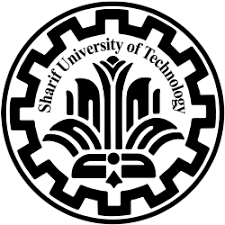

Hw 01

ali sadeghian 400101464

Fall 1402

# Theory Assignments

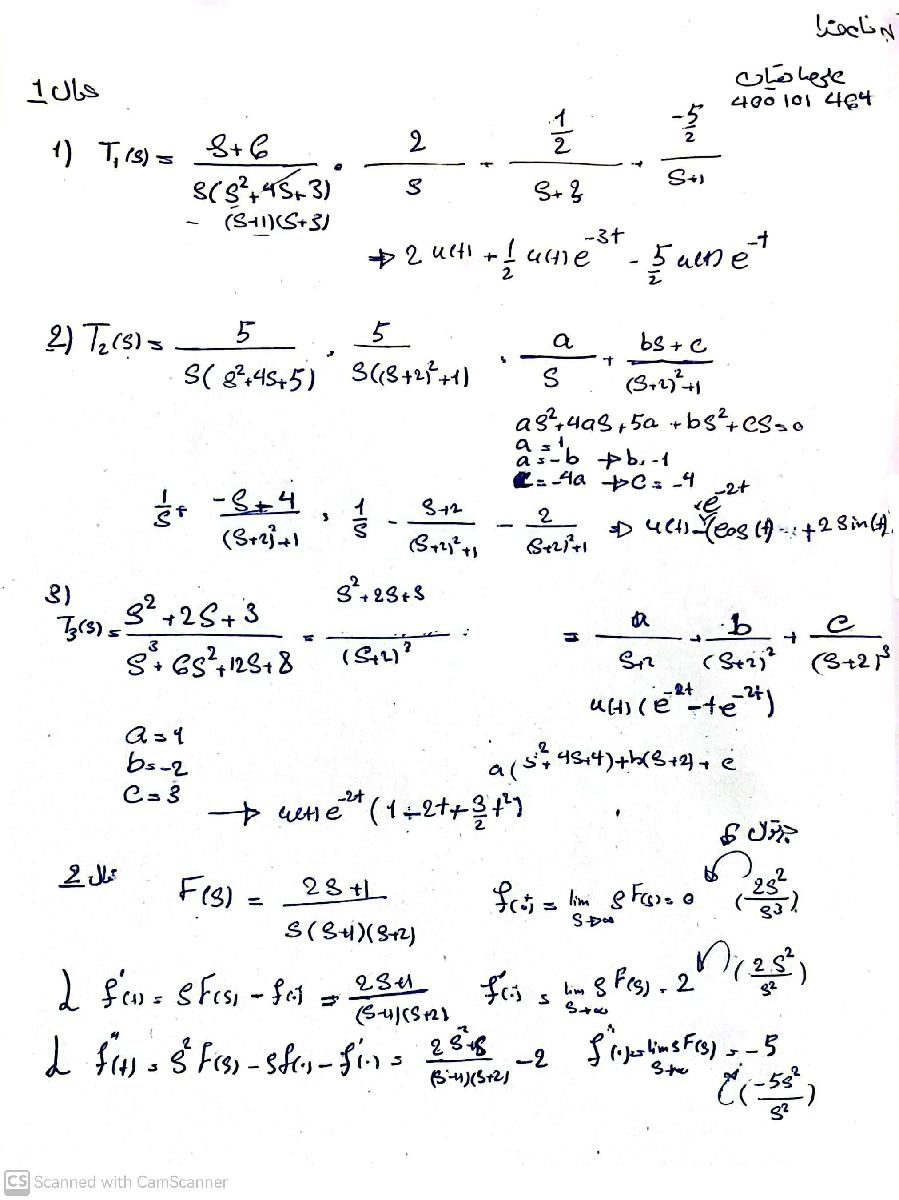

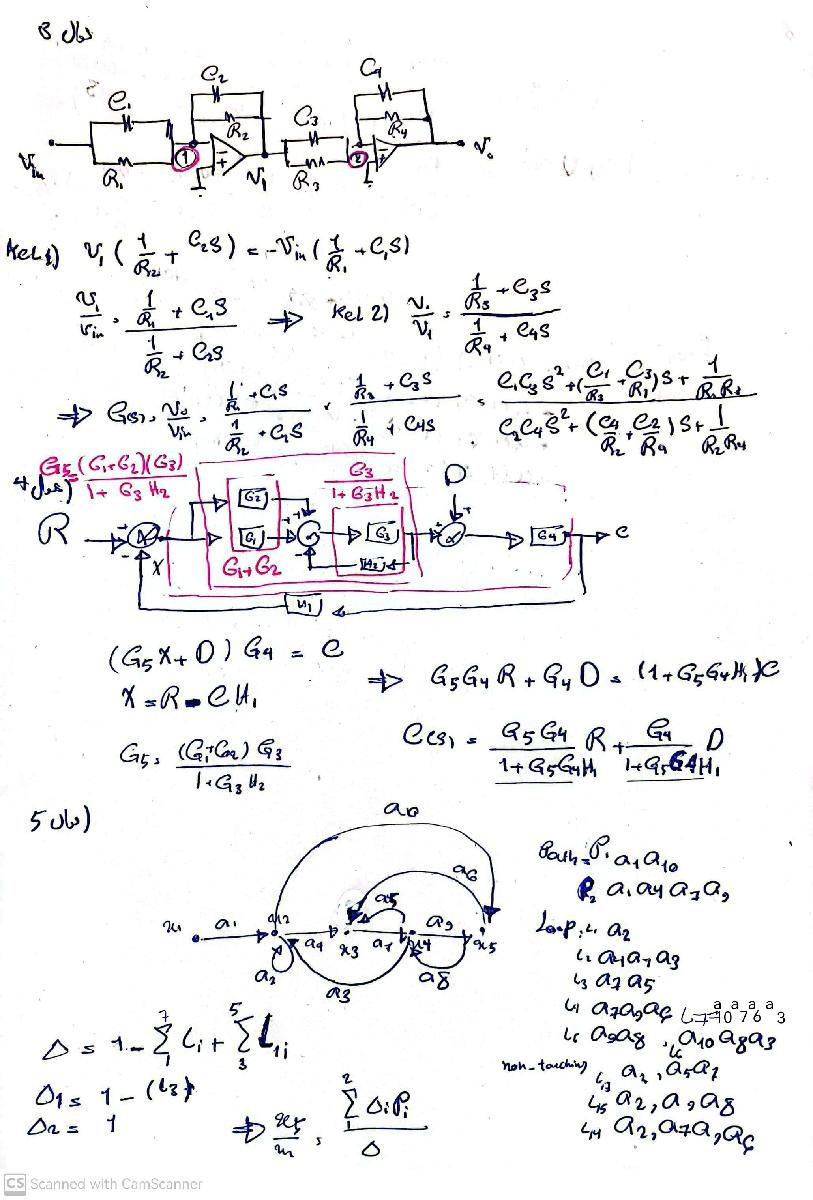

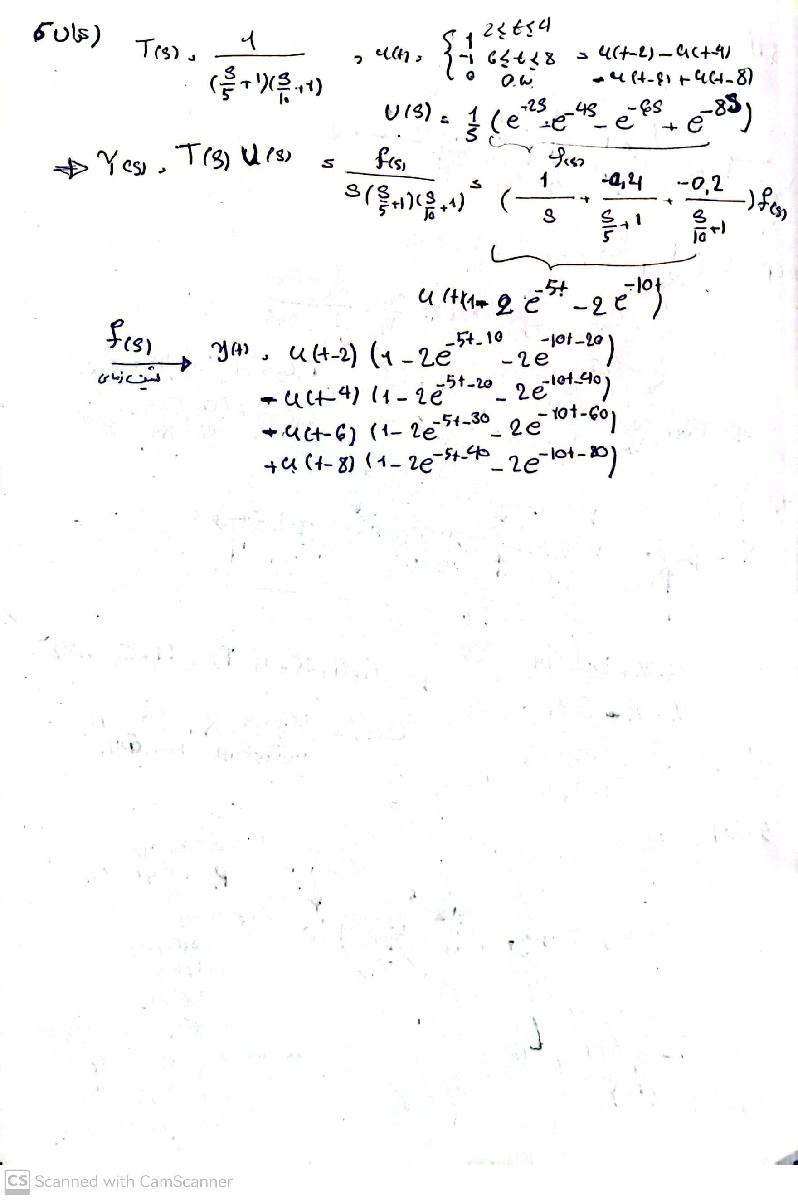

# MATLAB 

clear all
close all

# 7 Continues-Time Signals

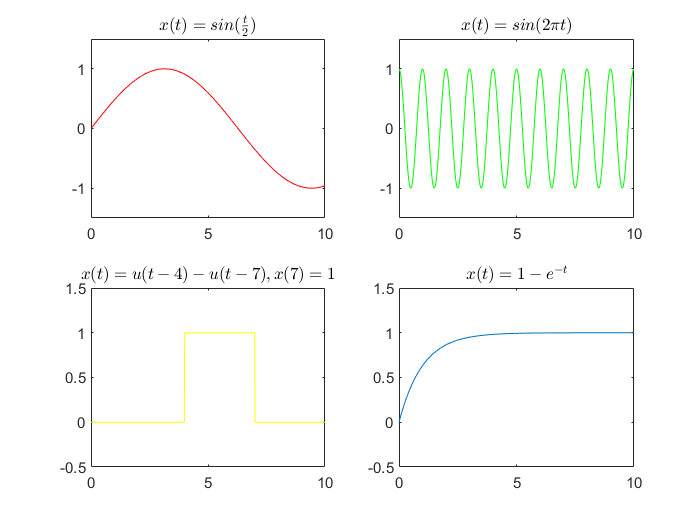

t_start = 0;
t_end = 10;

figure
subplot(2,2,1)
num = 1001; 
t = linspace(t_start,t_end,num);
x1 =  sin(t./2);
plot(t,x1,'Color','r')
title('$x(t)=sin(\frac{t}{2}) $','Interpreter','latex','FontSize',10)
xlim([0 10])
ylim([-1.5 1.5])


subplot(2,2,2)
num = 1001; 
t = linspace(t_start,t_end,num);
x2 =  cos(2*pi*t);
plot(t,x2,'Color','g')
title('$x(t)=sin(2\pi t) $','Interpreter','latex','FontSize',10)
xlim([0 10])
ylim([-1.5 1.5])


subplot(2,2,3)
num = 1001 ;
t = linspace(t_start,t_end,num);
x3 =  Step01(t-4)-Step00(t-7);
plot(t,x3,'Color','y')
title('$x(t)=u(t-4)-u(t-7),x(7)=1 $','Interpreter','latex','FontSize',10)
xlim([0 10])
ylim([-0.5 1.5])



subplot(2,2,4)
num = 1001; 
t = linspace(t_start,t_end,num);
x4 =  1 -exp(-t);
plot(t,x4)
title('$x(t)=1-e^{-t}$','Interpreter','latex','FontSize',10)
xlim([0 10])
ylim([-0.5 1.5])

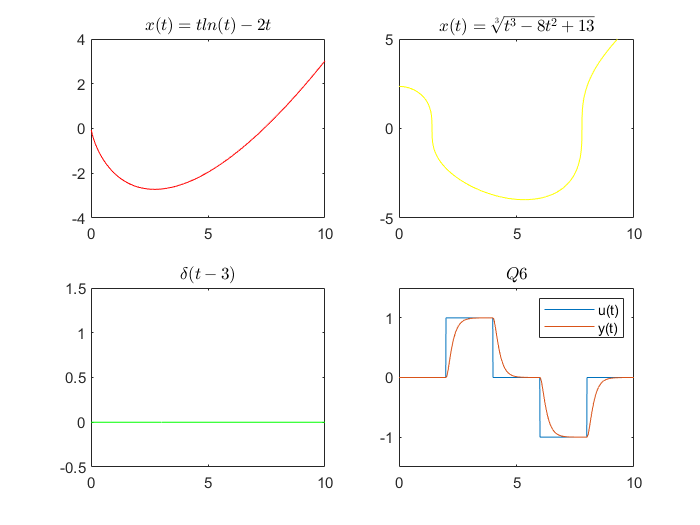

figure
subplot(2,2,1)
num = 1001 ;
t = linspace(t_start,t_end,num);
x5 =  t.*log(t)-2*t;
plot(t,x5,'Color','r')
title('$x(t)=tln(t)-2t$','Interpreter','latex','FontSize',10)
xlim([0 10])
ylim([-4 4])



subplot(2,2,2)
num = 1001; 
t = linspace(t_start,t_end,num);
x6 =  nthroot(t.^3-8*t.^2+13,3);
plot(t,x6,'Color','y')
title('$x(t)=\sqrt[3]{t^3-8t^2+13}$','Interpreter','latex','FontSize',10)
xlim([0 10])
ylim([-5 5])


subplot(2,2,3)
num = 1001; 
t = linspace(t_start,t_end,num);
x7 = dirac(t-3);
plot(t,x7,'Color','g')
title('$ \delta (t-3)$','Interpreter','latex','FontSize',10)
xlim([0 10])
ylim([-0.5 1.5])



num = 1001; 
t = linspace(t_start,t_end,num);
u =  Step01(t-2)-Step01(t-4)-Step01(t-6)+Step01(t-8);
y=Step01(t-2).*(1-2*exp(-5*(t-2))+exp(-10*(t-2)))-Step01(t-4).*(1-2*exp(-5*(t-4))+ ...
  exp(-10*(t-4)))-Step01(t-6).*(1-2*exp(-5*(t-6))+exp(-10*(t-6)))+ ...
  Step01(t-8).*(1-2*exp(-5*(t-8))+exp(-10*(t-8)));
subplot(2,2,4)
plot(t,u,t,y)
title('$Q6$','Interpreter','latex','FontSize',10)
legend("u(t)","y(t)")
xlim([0 10])
ylim([-1.5 1.5])

# 8 Numerical Solution of Ordinary Differential Equations

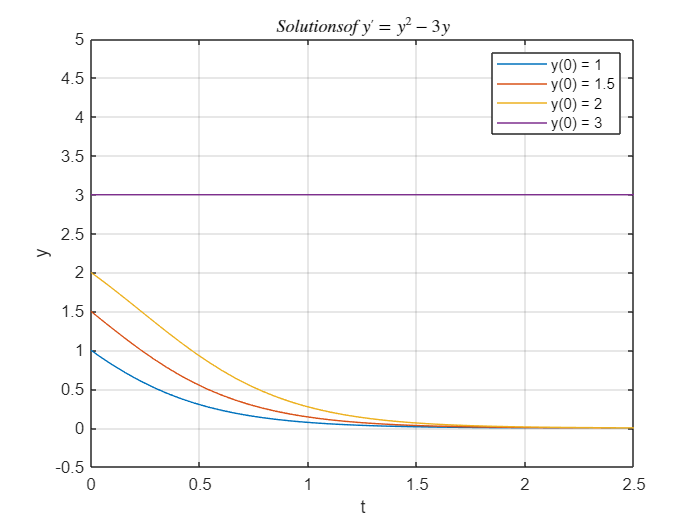

tspan = [0 2.5];
y0 = [1 1.5 2 3]; 

figure

[t, y] = ode45(@odefun, tspan, y0);

plot(t, y);
xlabel('Time');
ylabel('y(t)');
grid on
xlim([0 2.5])
ylim([-0.5 5])
xlabel('t')
ylabel('y')
legend("y(0) = 1","y(0) = 1.5","y(0) = 2","y(0) = 3")
title('$Solutions of y'' = y^{2}-3y$','interpreter','latex')

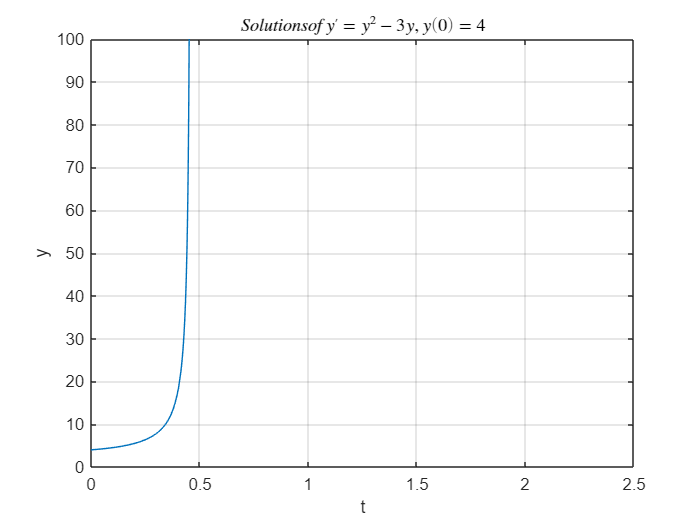


tspan = [0 0.46];
y0 = 4; 


[t, y] = ode45(@odefun, tspan, y0);

plot(t, y);
xlabel('Time');
ylabel('y(t)');
grid on
xlim([0 2.5])
ylim([0 100])
xlabel('t')
ylabel('y')
title('$Solutions of y'' = y^{2}-3y, y(0) = 4$','interpreter','latex')

# 9 Numerical Methods to Find the Response of a Linear System

lsim:


$$\frac{1}{\left(0\ldotp 2s+1\right)\left(0\ldotp 1s+1\right)}=\frac{1}{0\ldotp 02s^2 +0\ldotp 3s+1}\;$$


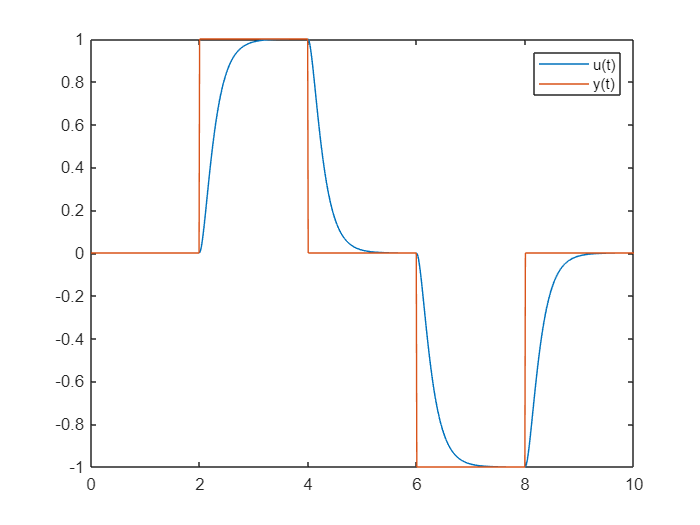

Ts = 0.01;
sys = tf(1,[0.02 0.3 1]);
t = 0:Ts:10;
u =  Step01(t-2)-Step01(t-4)-Step01(t-6)+Step01(t-8);
y0 =[0 0];
y = lsim(sys,u,t);
figure
plot(t,y,t,u)
legend("u(t)","y(t)")

Euler method:


$$\begin{array}{l}
\Rightarrow 0\ldotp 02{y^{\prime } }^{\prime } +0\ldotp 3y^{\prime } +y=u\Rightarrow y\left(n\right)=u\left(n\right)-\frac{0\ldotp 3}{h}\left(y\left(n\right)-y\left(n-1\right)\right)-\frac{0\ldotp 02}{h^2 }\left(y\left(n\right)-2y\left(n-1\right)+y\left(n-2\right)\right)\\
\Rightarrow \left(1+\frac{0\ldotp 3}{h}+\frac{0\ldotp 02}{h^2 }\right)y\left(n\right)=u\left(n\right)+\left(\frac{0\ldotp 3}{h}+\frac{0\ldotp 04}{h^2 }\right)y\left(n-1\right)-\frac{0\ldotp 02}{h^2 }y\left(n-2\right)\\
\Rightarrow y\left(n\right)=\frac{1}{\left(1+\frac{0\ldotp 3}{h}+\frac{0\ldotp 02}{h^2 }\right)}u\left(n\right)+\frac{\left(\frac{0\ldotp 3}{h}+\frac{0\ldotp 04}{h^2 }\right)}{\left(1+\frac{0\ldotp 3}{h}+\frac{0\ldotp 02}{h^2 }\right)}y\left(n-1\right)-\frac{\frac{0\ldotp 02}{h^2 }}{\left(1+\frac{0\ldotp 3}{h}+\frac{0\ldotp 02}{h^2 }\right)}y\left(n-2\right)
\end{array}$$


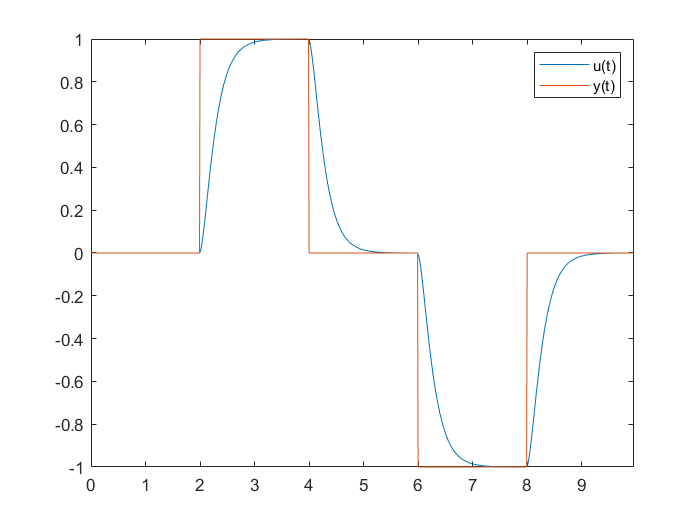

Ts = 0.01;
t = 0:Ts:10;
Y=zeros(size(t));
U=Step01(t-2)-Step01(t-4)-Step01(t-6)+Step01(t-8);

Y(1)=0;
Y(2)=0;

for i=3:length(Y)
    Y(i)=(1/(1+(0.3/(Ts))+(0.02/(Ts^2))))*(U(i)+((0.3/Ts) ...
        +(0.04/(Ts^2)))*Y(i-1)-(0.02/(Ts^2))*Y(i-2)); %f
end
figure
plot(t,Y,t,U)
legend("u(t)","y(t)")

# 10 Simulink

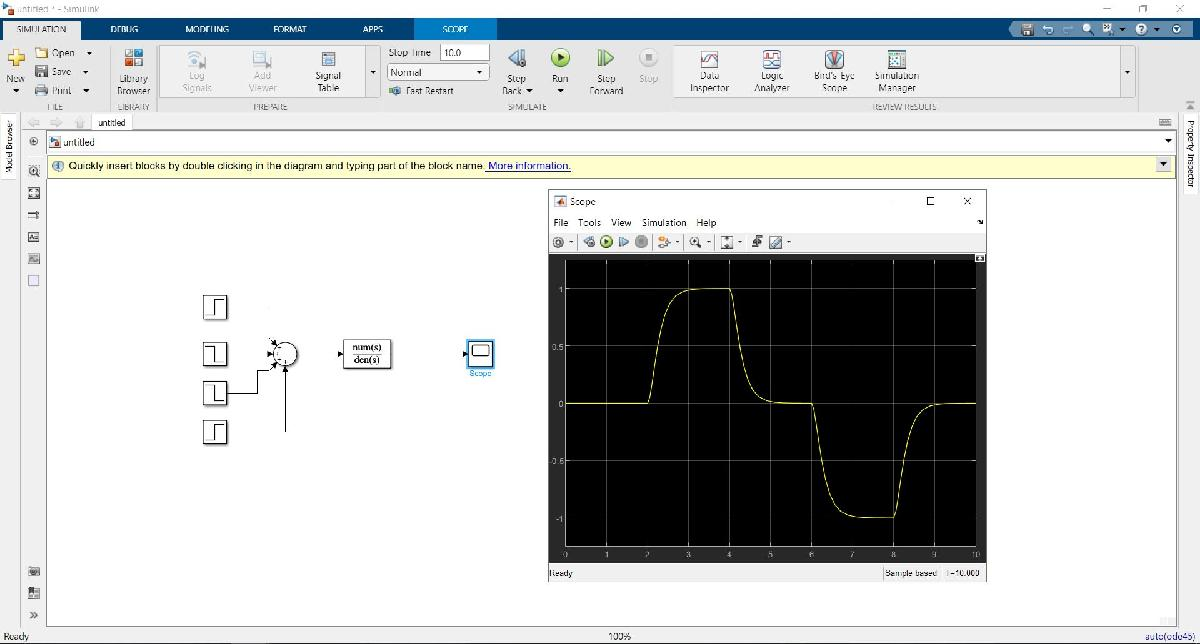

According to questions 8, 9, and 10, all outputs are equal to the answer in section 6 with proper accuracy

# Functions

function dydt = odefun(t, y)
    dydt = y.^2 - 3*y;
end

function [u] = Step01(C)
u = C;
s = length(C);
for i=1:s
    if C(i)>=0
        u(i)=1;
    else
        u(i)=0;
    end
end    
end
function [u] = Step00(C)
u = C;
s = length(C);
for i=1:s
    if C(i)>0
        u(i)=1;
    else
        u(i)=0;
    end
end    
end